# Python interop

## Connect to Python

!which python

/usr/bin/python


!python --version

Python 3.10.16


pyenv(Version="/usr/bin/python")

ans =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "/usr/bin/python"
          Library: "libpython3.10.so.1.0"
             Home: "/usr"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## Call Python from MATLAB

### Via a live task

% Python code input
pycode = [...
"import math",...
"res = math.sqrt(42)",...
"print(res)"...
];

try
    [res] = pyrun(pycode, ...
         [ "res" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

6.48074069840786


res = 6.4807


% Clear temporary variables from workspace and from Python
clear pycode;
res^2

ans = 42

### Via the py. prefix

py.math.sqrt(42)

ans = 6.4807

## Call Python packages

### Astropy

websave("get-pip.py","https://bootstrap.pypa.io/get-pip.py");
!python get-pip.py
!python -m pip --version
!python -m pip install astropy

% Import the Astropy Time module
astropy_time = py.importlib.import_module('astropy.time');

% Create a Time object from a string
time_str = '2023-10-01T12:00:00';
time_obj = astropy_time.Time(time_str)

time_obj =   Python Time with properties:

                T: [1×1 py.astropy.time.core.Time]
            cache: [1×1 py.collections.defaultdict]
    delta_ut1_utc: [1×1 py.numpy.ndarray]
           format: [1×4 py.str]
        in_subfmt: [1×1 py.str]
             info: [1×1 py.astropy.time.core.TimeInfo]
         isscalar: 1
              jd1: 2460219
              jd2: 0
         location: [1×1 py.NoneType]
             mask: [1×1 py.numpy.ndarray]
           masked: 0
             ndim: [1×1 py.int]
       out_subfmt: [1×1 py.str]
        precision: [1×1 py.int]
            scale: [1×3 py.str]
            shape: [1×0 py.tuple]
             size: [1×1 py.int]
         unmasked: [1×1 py.astropy.time.core.Time]
            value: [1×23 py.str]
        writeable: 1
           SCALES: [1×7 py.tuple]

    2023-10-01T12:00:00.000


time_obj.to_datetime

ans = datetime
   01-Oct-2023 12:00:00


### Obspy

!python -m pip install obspy

Defaulting to user installation because normal site-packages is not writeable

% Python code input
pycode2 = [...
"from obspy import UTCDateTime",...
"from obspy.clients.fdsn import Client",...
"",...
"# Initialize the FDSN client to connect to IRIS",...
"client = Client(""IRIS"")",...
"",...
"# Define the time period for the data (one minute of data)",...
"starttime = UTCDateTime(""2020-01-01T00:00:00"")",...
"endtime = starttime + 60  # 60 seconds later",...
"",...
"# Retrieve the waveform data",...
"st = client.get_waveforms(network=""IU"", station=""ANMO"", location=""00"", channel=""BHZ"",",...
"                          starttime=starttime, endtime=endtime)",...
"",...
"data = st.traces[0].data"...
];

try
    [data, st] = pyrun(pycode2, ...
         [ "data" "st" ])
catch ME6
    % Clear temporary variables from workspace and from Python
    clear pycode2;
    rethrow(ME6)
end

data =   Python ndarray:

   1779   1790   1790   1792   1804   1800   1794   1803   1813   1806   1803   1808   1806   1805   1800   1791   1797   1793   1778   1782   1780   1773   1768   1757   1755   1752   1735   1733   1736   1723   1720   1718   1709   1704   1698   1693   1686   1681   1673   1667   1666   1652   1651   1649   1637   1638   1628   1621   1621   1609   1609   1610   1597   1594   1598   1588   1580   1583   1581   1581   1577   1570   1579   1574   1566   1573   1570   1568   1572   1571   1576   1580   1584   1585   1593   1603   1600   1606   1613   1610   1612   1624   1625   1621   1633   1640   1645   1652   1658   1662   1668   1673   1669   1686   1690   1687   1704   1705   1717   1723   1722   1738   1736   1741   1753   1747   1753   1758   1752   1754   1760   1760   1757   1761   1761   1760   1764   1760   1758   1764   1760   1751   1754   1750   1755   1756   1741   1745  

st =   Python Stream with properties:

    traces: [1×1 py.list]

    1 Trace(s) in Stream:
    IU.ANMO.00.BHZ | 2020-01-01T00:00:00.019538Z - 2020-01-01T00:00:59.994538Z | 40.0 Hz, 2400 samples



% Clear temporary variables from workspace and from Python
clear pycode2;
st.traces{1}.stats

ans =   Python Stats with properties:

             npts: [1×1 py.int]
          network: [1×2 py.str]
    sampling_rate: 40
        starttime: [1×1 py.obspy.core.utcdatetime.UTCDateTime]
            calib: 1
          channel: [1×3 py.str]
            mseed: [1×1 py.obspy.core.util.attribdict.AttribDict]
            delta: 0.0250
       processing: [1×1 py.list]
          station: [1×4 py.str]
         location: [1×2 py.str]
          endtime: [1×1 py.obspy.core.utcdatetime.UTCDateTime]

                   network: IU
                   station: ANMO
                  location: 00
                   channel: BHZ
                 starttime: 2020-01-01T00:00:00.019538Z
                   endtime: 2020-01-01T00:00:59.994538Z
             sampling_rate: 40.0
                     delta: 0.025
                      npts: 2400
                     calib: 1.0
    _fdsnws_dataselect_url: http://service.iris.ed

data = int32(data)

data = 1×2400 int32 row vector
   1779   1790   1790   1792   1804   1800   1794   1803   1813   1806   1803   1808   1806   1805   1800   1791   1797   1793   1778   1782   1780   1773   1768   1757   1755   1752   1735   1733   1736   1723   1720   1718   1709   1704   1698   1693   1686   1681   1673   1667   1666   1652   1651   1649   1637   1638   1628   1621   1621   1609


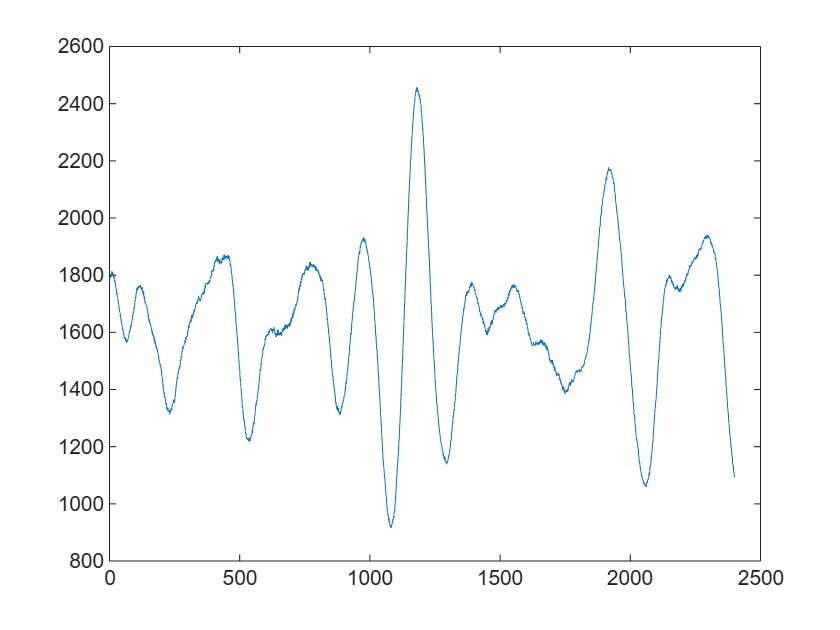

plot(data)